# Matlab Tutorial 1 Spring 2025

## Arithmetic operations 

10 - 13 + 4*2/5

ans = -1.4000

(10 - (13 + 4 * 2)) / 5

ans = -2.2000

sqrt(2)

ans = 1.4142


% format long vs short 
format long
2^(-52)

ans =      2.220446049250313e-16


format short
2^(-52)

ans = 2.2204e-16

## Assigning variables 

x = 4.5; 
y = x^3 - 2/x + 1;

%Y^2 - 3 % case sensitive!

x=3.5, y=-5.0, x^3-y % group the assignments on the same line

x = 3.5000

y = -5

ans = 47.8750


x=3.5; y=-5.0; x^3-y % semi-colon to hide the output

ans = 47.8750


myvec = [5 6 7 8]

myvec =      5     6     7     8



%(upward arrow to trace history in command line)
%(clc to clear command line)

To clear variables:

%clear x
%clear y z
clear all

## Pre-defined constants and Built-in functions

Pre-defined constants:

pi % pi

ans = 3.1416

disp(pi) % different display/print out

    3.1416




i,j % sqrt(-1)

ans = 0.0000 + 1.0000i

ans = 0.0000 + 1.0000i


inf % infinity 

ans = Inf


NaN % not a number

ans = NaN


ans % result of previous computation 

ans = NaN

Built-in functions:

log(10) % log(10)

ans = 2.3026


exp(1) % e

ans = 2.7183


% trig functions in radians
sin(45) 

ans = 0.8509

sin(45/180*pi)

ans = 0.7071

tan(pi) % note the roundoff 

ans = -1.2246e-16


sqrt(2) % square root of 2

ans = 1.4142

## For loops 

for i = 1:0.5:5
    i
end 

i = 1

i = 1.5000

i = 2

i = 2.5000

i = 3

i = 3.5000

i = 4

i = 4.5000

i = 5


for cat=1:2:6, cat, end 

cat = 1

cat = 3

cat = 5


% nested loop
for i = 1:3
    for j = 1:3
        i+j
    end 
end 

ans = 2

ans = 3

ans = 4

ans = 3

ans = 4

ans = 5

ans = 4

ans = 5

ans = 6

## Vectors 

v1 = [4.5 3 -1.2] % row vector

v1 =     4.5000    3.0000   -1.2000


length(v1) % obtain length

ans = 3

v2 = [4;-5;2] % column vector

v2 =      4
    -5
     2


size(v1), size(v2) % compare sizes

ans =      1     3


ans =      3     1


v2(2) % inspect entry

ans = -5

v2(2)=5 % redefine entry

v2 =      4
     5
     2



% Colon
1:4

ans =      1     2     3     4


1:0.02:1.2

ans =     1.0000    1.0200    1.0400    1.0600    1.0800    1.1000    1.1200    1.1400    1.1600    1.1800    1.2000



% Vector operations
v1*v2

ans = 30.6000


v3 = [1,5,2]

v3 =      1     5     2


v3' % transpose

ans =      1
     5
     2


v3'' % undoes itself if applied twice

ans =      1     5     2



v2+v3

ans =      5     9     6
     6    10     7
     3     7     4


v2+v3'

ans =      5
    10
     4



% Element-wise operations:
v2.*v3 

ans =      4    20     8
     5    25    10
     2    10     4


v2./v3

ans =     4.0000    0.8000    2.0000
    5.0000    1.0000    2.5000
    2.0000    0.4000    1.0000


## Matrices

% Matrices
A = [0 2; 1 3; 4 -1];
B = [1 1; 0 0; 1 2];
C = [1 0 1; -2 3 -1];
A(3,2)

ans = -1

%A(2,3)  % bad

% Special Matrices:
zeros(3,4)

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0


ones(5,6)

ans =      1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1


eye(5)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1



% Concatenating Matrices:
D = zeros(4,2)

D =      0     0
     0     0
     0     0
     0     0


E = [D, ones(4,1)] 

E =      0     0     1
     0     0     1
     0     0     1
     0     0     1



% Matrix operations:
A + B

ans =      1     3
     1     3
     5     1


A*C

ans =     -4     6    -2
    -5     9    -2
     6    -3     5


%A*B % bad

% Element-wise operations: 
A.*B

ans =      0     2
     0     0
     4    -2


B.^2

ans =      1     1
     0     0
     1     4


B./A

ans =        Inf    0.5000
         0         0
    0.2500   -2.0000




% Sparse Matrices: 
% [Ref: Matlab Primer by Kermit Sigmon] 
a = [1 2 3 4 4 4]; b = [1 2 3 1 2 3];  
s = [5 6 7 8 9 10];
% help sparse
S = sparse(a,b,s,4,3), full(S)

S = 4×3 sparse double matrix (6 nonzeros)
   (1,1)        5
   (4,1)        8
   (2,2)        6
   (4,2)        9
   (3,3)        7
   (4,3)       10


ans =      5     0     0
     0     6     0
     0     0     7
     8     9    10


## Excercise 1

(a) Create a length 1000 vector, v, with entries given by 


$$v(i) = sin(i)$$


using one for loop.

(b) Create a 1000 x 1000 matrix, M, with entries given by 


$$M(i, j) = cos(i) cos(j)$$


using two for loops.

(c) Find a more efficient way to create the matrix M and vector v. 

clear v M 

% a
for i = 1:1000
    v(i) = sin(i);
end 

% b 
for i = 1:1000
    for j=1:1000
        M(i, j) = cos(i)*cos(j);
    end
end 

M

M =     0.2919   -0.2248   -0.5349   -0.3532    0.1533    0.5188    0.4073   -0.0786   -0.4923   -0.4534    0.0024    0.4559    0.4903    0.0739   -0.4105   -0.5174   -0.1487    0.3568    0.5342    0.2205   -0.2959   -0.5403   -0.2879    0.2292    0.5355    0.3495   -0.1578   -0.5201   -0.4042    0.0833    0.4942    0.4507   -0.0072   -0.4585   -0.4883   -0.0691    0.4136    0.5160    0.1441   -0.3603   -0.5335   -0.2161    0.2999    0.5402    0.2838   -0.2335   -0.5362   -0.3459    0.1624    0.5214
   -0.2248    0.1732    0.4120    0.2720   -0.1180   -0.3996   -0.3137    0.0605    0.3792    0.3492   -0.0018   -0.3512   -0.3776   -0.0569    0.3161    0.3985    0.1145   -0.2748   -0.4114   -0.1698    0.2279    0.4161    0.2217   -0.1765   -0.4125   -0.2692    0.1216    0.4006    0.3113   -0.0642   -0.3807   -0.3472    0.0055    0.3531    0.3761    0.0533   -0.3185   -0.3975   -0.1110    0.2775    0.4109    0.1665   -0.2310   -0.4161   -0.2186    0.1798    0.4130    0.2664   -0.1251   -0


% c

M_efficient = cos(1:1000).*cos(1:1000)'

M_efficient =     0.2919   -0.2248   -0.5349   -0.3532    0.1533    0.5188    0.4073   -0.0786   -0.4923   -0.4534    0.0024    0.4559    0.4903    0.0739   -0.4105   -0.5174   -0.1487    0.3568    0.5342    0.2205   -0.2959   -0.5403   -0.2879    0.2292    0.5355    0.3495   -0.1578   -0.5201   -0.4042    0.0833    0.4942    0.4507   -0.0072   -0.4585   -0.4883   -0.0691    0.4136    0.5160    0.1441   -0.3603   -0.5335   -0.2161    0.2999    0.5402    0.2838   -0.2335   -0.5362   -0.3459    0.1624    0.5214
   -0.2248    0.1732    0.4120    0.2720   -0.1180   -0.3996   -0.3137    0.0605    0.3792    0.3492   -0.0018   -0.3512   -0.3776   -0.0569    0.3161    0.3985    0.1145   -0.2748   -0.4114   -0.1698    0.2279    0.4161    0.2217   -0.1765   -0.4125   -0.2692    0.1216    0.4006    0.3113   -0.0642   -0.3807   -0.3472    0.0055    0.3531    0.3761    0.0533   -0.3185   -0.3975   -0.1110    0.2775    0.4109    0.1665   -0.2310   -0.4161   -0.2186    0.1798    0.4130    0.2664   -0

## Solving linear systems

We wish to solve a linear system of the form $Ax=b$.

A = [2 -1 3; -4 6 -5; 6 13 16];
b = [13; -28; 37];

det(A) % nonzero

ans = 24.0000


rref([A,b]) % reduced 

ans =      1     0     0     3
     0     1     0    -1
     0     0     1     2


% backslash operator solves the system
x = A\b

x =     3.0000
   -1.0000
    2.0000


## Excercise 2

Solve a linear system of the form $Ax=b$ using both \ and via computing the inverse (see 'help inv'). Compare the two results,.

A = [5 -1 5; -1 2.5 -7; 6 30 1.6]; 
det(A) 

ans = 885.4000


b = [1; 2; pi]; % choose your own
x_inv = inv(A)*b

x_inv =     0.5646
    0.0111
   -0.3624



x = A\b

x =     0.5646
    0.0111
   -0.3624



A*x-b % residual for \

ans =      0
     0
     0


A*x_inv-b % residual for inv

ans = 1.0e-15 *

   -0.4441
    0.4441
    0.4441


abs(x_inv-x) % difference between results 

ans = 1.0e-15 *

    0.1110
    0.0347
         0


## Functions

scalarmul_inline = @(v, alpha) alpha*v;

output_inline = scalarmul_inline([1 2 3], 2)

output_inline =      2     4     6



output = scalarmul([1 2 3], 2) % scalarmul(v,alpha) see .m file 

output =      2     4     6


## Plotting 

### 1D

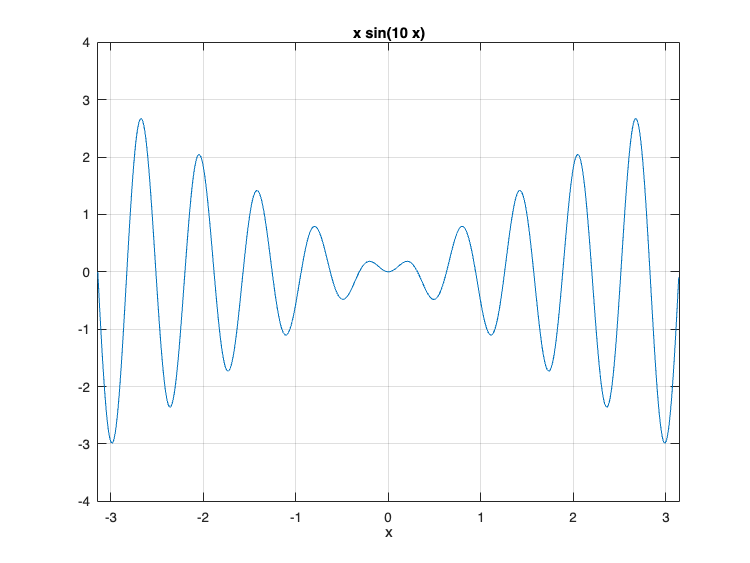

n = 10;
x = -pi:0.01:pi;
y = x.*sin(n*x); 

plot(x,y); 
grid on;
axis([-pi,pi,-4,4]); 
xlabel('x'); 
title( ['x sin(',num2str(n),' x)'] );

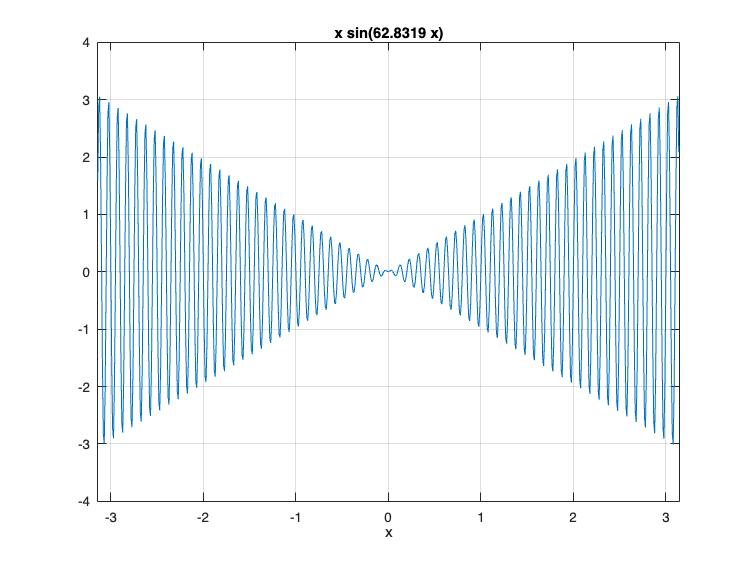

% function plotxsin(n) in .m file to plot x*sin(n*x)
plotxsin(20*pi)

### 2D

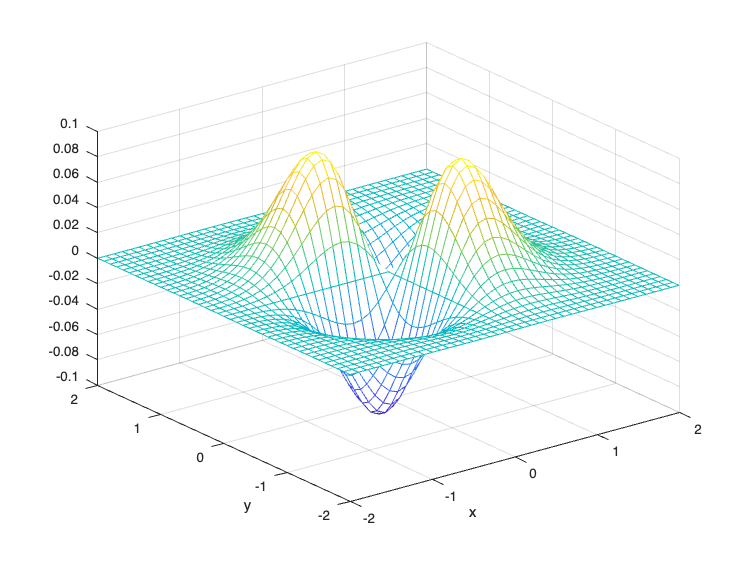

[X,Y] = meshgrid(-2:0.1:2,-2:0.1:2);
f = -X.*Y.*exp(-2*(X.^2+Y.^2));

figure(1)
mesh(X,Y,f),xlabel('x'),ylabel('y'),grid on;

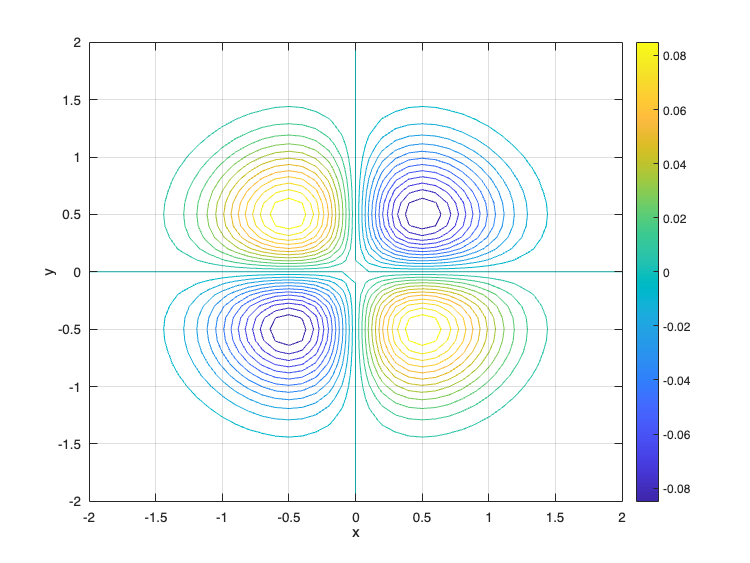

figure(2)
contour(X,Y,f, 25),xlabel('x'),ylabel('y'),grid on; colorbar;

## Excercise 3

Fill in the missing code to create a plot with two curves: $y_1(x) = e^x, \quad y_2(x) = x^2$.

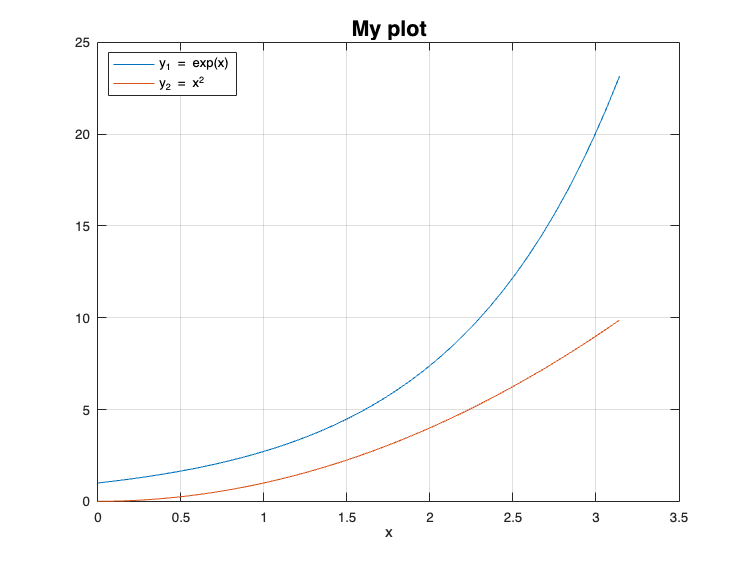

x = 0:pi/40:pi; % define x
y1 = exp(x);  % define y_1
y2 = x.^2; % define y_2

clf;
plot(x, y1) % plot y_1 
hold on % 
plot(x, y2) % plot y_2
hold off
xlabel('x') % label axes
title('My plot', 'FontSize', 16) % create a title
legend('y_1 = exp(x)', 'y_2 = x^2 ', 'location', 'northwest', 'FontSize', 10) % create a legend (see help legend)
grid on

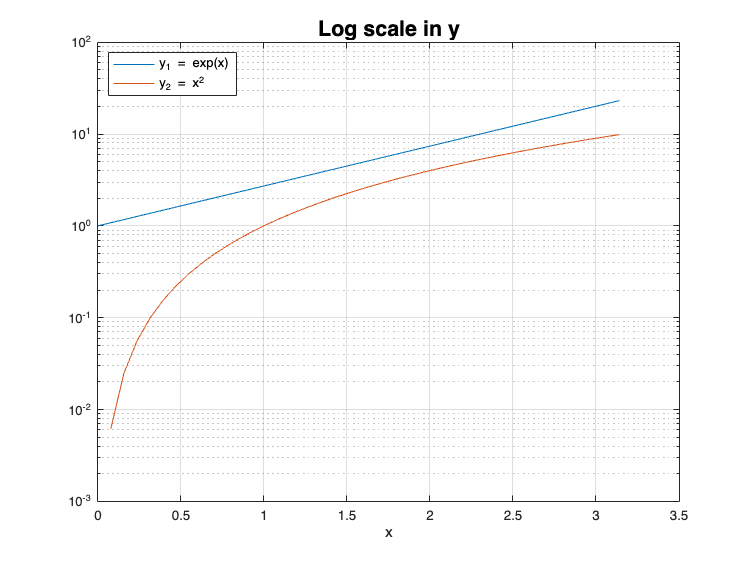

% now with semilogy for a different scale
clf;
semilogy(x, y1) % plot y_1
hold on
semilogy(x, y2) % plot y_2
hold off
xlabel('x') % label axes
title('Log scale in y', 'FontSize', 16)  % create a title
legend('y_1 = exp(x)', 'y_2 = x^2 ', 'location', 'northwest', 'FontSize', 10) % create a legend (see help legend)
grid on